# Laboratorium 10

### Linearyzacja układów nieliniowych

Janusz Pawlicki

## 1. Wstęp

Układy liniowe to układy, których opis ma postać zależności liniowych. W szczególności, musi być spełniona zasada superpozycji, która stanowi, że reakcja układu liniowego na wymuszenie o postaci:

ma postać:

przy czym y1 i y2 stanowią wynik oddziaływania oddzielnych wymuszeń u1 i u2 (c1 i c2 są dowolnymi stałymi). Zatem w opisie równania liniowego nie mogą występować żadne operacje nieliniowe na zmiennych układu (np. iloczyny lub potęgi zmiennych), a parametry układu (współczynniki równań) nie mogą zależeć od zmiennych.

Aby uzyskać model liniowy układu nieliniowego należy przeprowadzić tzw. linearyzację. Jest to uproszczenie układu nieliniowego w taki sposób, że charakterystykę nieliniową przybliża się lokalnie (tzn. w pewnym obszarze) odpowiednio dobraną zależnością liniową.

Załóżmy, że jest dany model dynamiki układu o postaci:

gdzie y jest wyjściem, a u wejściem układu. Liniowa aproksymacja takiego układu może być przeprowadzona za pomocą rozwinięcia równania w szereg Taylora i odrzucenia członów wyższego rzędu, czyli:

gdzie (*ū* ,ȳ) oznacza tzw. punkt pracy, wokół którego dokonujemy linearyzacji. Taka linearyzacja jest możliwa tylko lokalnie, w otoczeniu wybranego punktu pracy i ma sens tylko dla małych odchyleń od tego punktu. To znaczy że odchylenie y - ȳ punktu bieżącego y od punktu ȳ, wokół którego dokonujemy rozwinięcia, musi być dostatecznie małe (to samo tyczy się oczywiście odchylenia (u - *ū*).

Z definicji, w punkcie pracy występuje tzw. stan ustalony, wobec tego pierwszy człon z szeregu Taylora się zeruje:

Wprowadzając jeszcze tzw. zmienne odchyłkowe:y' = y - ȳ oraz       u' = u - *ū* (czyli odchyłki od punktu pracy), równanie Taylora można uprościć do postaci:

W ten sposób otrzymujemy zależność liniową, ale sensowną tylko w pobliżu punktu pracy.

## 2. Obiekt nieliniowy

Obiektem, który będziemy linearyzować jest model zbiornika ze stałym dopływem i wypływem oraz grzaniem, z założeniem idealnego mieszania. Model taki można opisać równaniami różniczkowymi wyprowadzonymi na podstawie zasady zachowania masy:

i zasady zachowania energii:

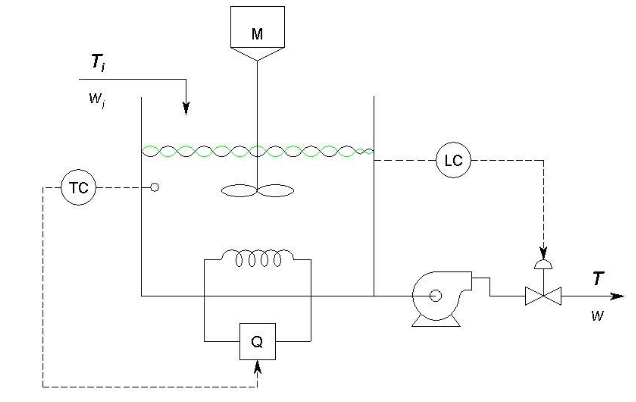

## 3. Symulacja modelu nieliniowego

Dla wartości:

Q = 12000 [W],

w = 0.4 [kg/s],

wi = 0.4 [kg/s],

Ti = 293 [K],

T0 = 293 [K],

V0 = 0.04 [m^3].

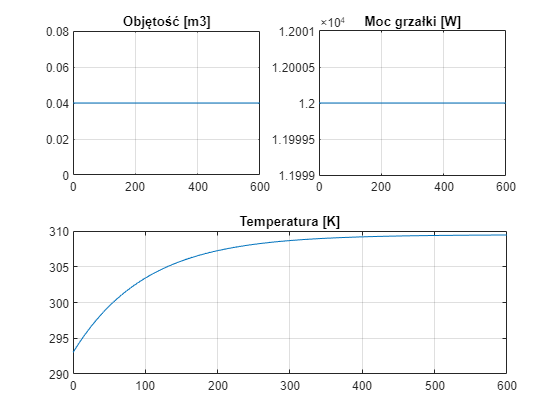

% function nieliniowy(Q) %podajemy moc grzałki jako wejście
% V0=0.04;
% T0=293;
% w=0.4;
% wi=0.4;
% Ti=293;
% [t,x] = ode45(@zbiornik_stan,[0:1:600],[V0,T0],[],wi,w,Ti,Q);
% subplot(2,2,1)
%     plot(t,x(:,1))
%     grid on;`
%     axis([0 600 0 max(x(:,1))*2])
%     title('Objętość [m3]')
% subplot(2,2,2)
%     A=zeros(1,length(t));
%     for a=1:length(t)
%         A(a)=Q;
%     end
%     plot(t,A)
%     grid on;
%     title('Moc grzałki [W]')
% subplot(2,2,[3,4])
%     plot(t,x(:,2))
%     grid on;
%     title('Temperatura [K]')
% end

nieliniowy(12000)

## 4. Stan ustalony

Model w simulinku:

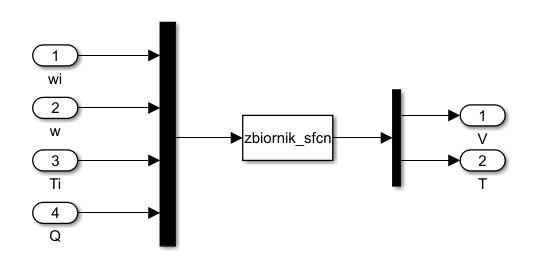

S-funkcja zbiornik_sfcn:

% function [sys,x0,str,ts]=zbiornik_sfcn(t,x,u,flag,V0,T0)
% switch flag
%  case 0 % inicjalizacja
%     str = [];
%     ts = [0 0];
%     s = simsizes;
%         s.NumContStates = 2; % liczba stanów ciągłych
%         s.NumDiscStates = 0; % liczba stanów dyskretnych
%         s.NumOutputs = 2; % liczba wyjść
%         s.NumInputs = 4; % liczba wejść
%         s.DirFeedthrough = 0; % wejście nie przenosi się bezpośrednio na wyjście
%         s.NumSampleTimes = 1; % czas próbkowania
%     sys = simsizes(s);
%     x0 = [V0, T0];
%  case 1 % pochodne
%     wi = u(1);
%     w = u(2);
%     Ti = u(3);
%     Q = u(4);
%     sys = zbiornik_stan(t,x,wi,w,Ti,Q);
%  case 3 % wyjście
%     sys = x;
%  case {2 4 9}
%     sys =[];
%  otherwise
%      error(['unhandled flag =',num2str(flag)]);
% end

Dla wartości podanych w konspekcie, wykresy stanu ustalonego:

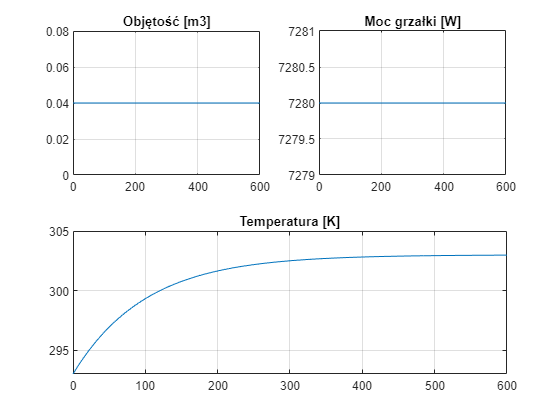

% clear;
% X0=[0.04;303];         %– wektor stanu (w stanie ustalonym)
% U0=[0.4;0.4;293;7000]; %– wektor wejść [wi,w,Ti,Q]
% Y0=[0.04;303];         %– wektor wyjść (chcemy aby objętość cieczy w zbiorniku
%                        % była stała i wynosiła 0.04 m3 oraz aby temperatura
%                        % wyjściowa wynosiła 303 K
% IX=[];      % – wartości stanu nie są blokowane
% IU=[1;2;3]; % – pierwsza (wi), druga (w) i trzecia zmienna 
%             % wejściowa (Ti) jest zablokowana
% IY=[1;2];   % – pierwsza (V=0.04) i druga (T=303) zmienna 
%             % wyjściowa jest zablokowana
% V0=0.04;
% T0=293;            
% [x,u,y,dx]=trim('zbiornik_sys',X0,U0,Y0,IX,IU,IY);
%
% nieliniowy(u(4)) %- wyświetlenie wykresu

stan_ustalony

## 5. Model liniowy

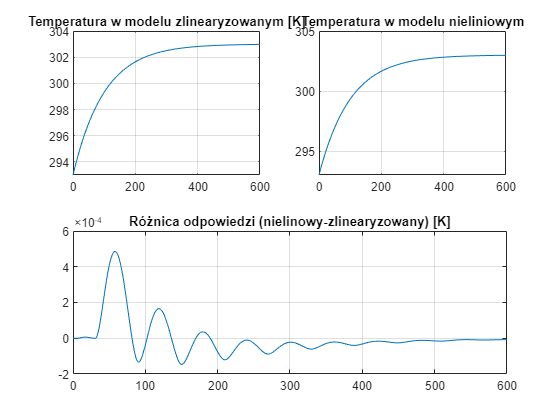

% stan_ustalony;
% %U0=[0.4;0.4;293;7000]; – wektor wejść [wi,w,Ti,Q]
% %Q=u(4) - moc grzałki ze stanu ustalonego
% t=0:1:600;
%
% [A,B,C,D] = linmod('zbiornik_sys', x, u);
%     U=zeros(length(t),4); %ponieważ warunki w trakcie są niezmienne
%     x0=[V0-x(1),T0-x(2)]; %startowa odchyłka od stanu ust.
% [y_lin,t_lin] = lsim(A,B,C,D,U,t,x0);
% y=y_lin(:,2)+303; %temperatura po linearyzacji
%
% [t_nlin,y_nlin] = ode45(@zbiornik_stan,[0:1:600],[V0,T0],[],U0(1),U0(2),U0(3),u(4));
% dif=y_nlin(:,2)-y; %różnica odpowiedzi
%
% subplot(2,2,1)
%     plot(t,y)
%     grid
%     title('Temperatura w modelu zlinearyzowanym [K]')
% subplot(2,2,2)
%     plot(t,y_nlin(:,2))
%     grid
%     title('Temperatura w modelu nieliniowym')
% subplot(2,2,[3,4])
%     plot(t,dif)
%     grid
%     title('Różnica odpowiedzi (nielinowy-zlinearyzowany) [K]')

liniowy